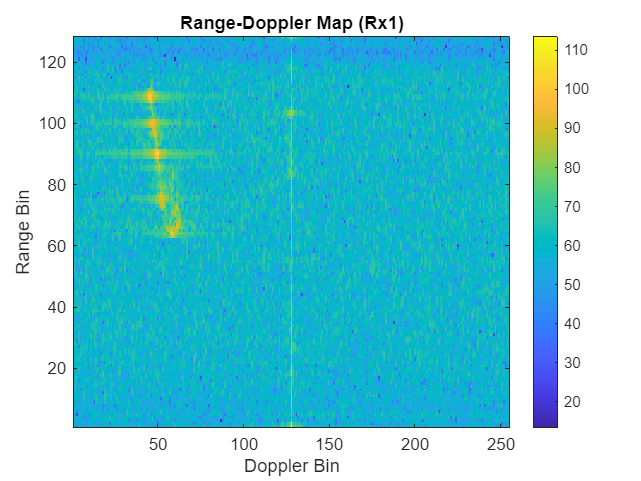

% Load data
data = load("D:\Automotive\Automotive\2019_05_29_pcms005\radar_raw_frame\000015.mat");
adc = data.adcData; % [128, 255, 4, 2]

% Convert to complex
adcComplex = squeeze(adc(:,:,:,1)) + 1j * squeeze(adc(:,:,:,2)); % [128, 255, 4]

% Select one Rx antenna
rxIndex = 1;
adc_rx = adcComplex(:,:,rxIndex); % [128 samples, 255 chirps]

% Apply Hann window in fast time (samples)
hann_win = hann(128); % column vector
windowed_adc = adc_rx .* hann_win; % broadcasted multiplication

% Perform Range FFT
range_fft = fft(windowed_adc, 128, 1); % FFT along rows (fast time)

% Perform Doppler FFT
doppler_fft = fftshift(fft(range_fft, 255, 2), 2); % FFT along chirps (slow time)

% Compute magnitude in dB
rd_map = 20*log10(abs(doppler_fft) + 1e-6); % add epsilon to avoid log(0)

% Plot RD map
figure;
imagesc(rd_map);
xlabel('Doppler Bin');
ylabel('Range Bin');
title('Range-Doppler Map (Rx1)');
colorbar;
axis xy;